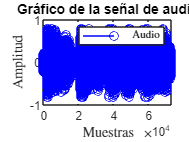

load('handel.mat')

frecuencia = Fs;
audio = y;

num_elementos_y = length(audio);
np = (1:1:num_elementos_y);
nd = (1:1:num_elementos_y);
nde = (1:1:num_elementos_y);
ns = (1:1:num_elementos_y);


% Gráfico de la señal de audio
figure;
stem(np, audio, 'b');
title('Gráfico de la señal de audio');
legend('Audio', 'Interpreter', 'latex');
xlabel('Muestras', 'Interpreter', 'latex');
ylabel('Amplitud', 'Interpreter', 'latex');

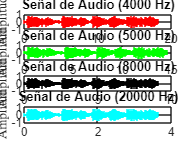


% valores de tiempo para cada frecuencia de muestreo
np = (0:length(audio) - 1) / 4000;
nd = (0:length(audio) - 1) / 5000;
nde = (0:length(audio) - 1) / 8000;
ns = (0:length(audio) - 1) / 20000;

% Grafica la señal con frecuencia de muestreo de 4000 Hz
subplot(4, 1, 1);
stem(np, audio, 'r', 'Marker', 'none');
title('Señal de Audio (4000 Hz)');
xlabel('Tiempo (s)', 'Interpreter', 'latex');
ylabel('Amplitud', 'Interpreter', 'latex');

% Grafica la señal con frecuencia de muestreo de 5000 Hz
subplot(4, 1, 2);
stem(nd, audio, 'g', 'Marker', 'none');
title('Señal de Audio (5000 Hz)');
xlabel('Tiempo (s)', 'Interpreter', 'latex');
ylabel('Amplitud', 'Interpreter', 'latex');

% Grafica la señal con frecuencia de muestreo de 8000 Hz
subplot(4, 1, 3);
stem(nde, audio, 'k', 'Marker', 'none');
title('Señal de Audio (8000 Hz)');
xlabel('Tiempo (s)', 'Interpreter', 'latex');
ylabel('Amplitud', 'Interpreter', 'latex');

% Grafica la señal con frecuencia de muestreo de 20000 Hz
subplot(4, 1, 4);
stem(ns, audio, 'c', 'Marker', 'none');
title('Señal de Audio (20000 Hz)');
xlabel('Tiempo (s)', 'Interpreter', 'latex');
ylabel('Amplitud', 'Interpreter', 'latex');


s40 = resample(audio, 4000, Fs);

Incorrect number or types of inputs or outputs for function 'resample'.

s50 = resample(audio, 5000, Fs);
s80 = resample(audio, 8000, Fs);
s200 = resample(audio, 20000, Fs);


len = min([length(s40), length(s50), length(s80), length(s200)]);
sumaSenal = s40(1:len) + s50(1:len) + s80(1:len) + s200(1:len);

sound(sumaSenal, frecuencia); 

figure;
stem(sumaSenal, 'b', 'Marker', 'none');
title('Suma de las Señales');
xlabel('Tiempo (s)', 'Interpreter', 'latex');
ylabel('Amplitud', 'Interpreter', 'latex');


spacing = 2000;
totalLen = length(s40) + spacing + length(s50) + spacing + length(s80) + spacing + length(s200);

datosConcatenados = zeros(totalLen, 1);

datosConcatenados(1:length(s40)) = s40;
datosConcatenados(length(s40) + spacing + 1:length(s40) + spacing + length(s50)) = s50;
datosConcatenados(length(s40) + spacing*2 + length(s50) + 1:length(s40) + spacing*2 + length(s50) + length(s80)) = s80;
datosConcatenados(length(s40) + spacing*3 + length(s50) + length(s80) + 1:length(s40) + spacing*3 + length(s50) + length(s80) + length(s200)) = s200;

figure;
stem(datosConcatenados, 'b', 'Marker', 'none');
title('Concatenación de Señales');
xlabel('Muestras', 'Interpreter', 'latex');
ylabel('Amplitud', 'Interpreter', 'latex');
%sound(datosConcatenados, frecuencia);


len = length(datosConcatenados);
invertida = zeros(len, 1);
for i = 1:len
    invertida(i) = datosConcatenados(len - i + 1);
end

figure;
stem(invertida, 'b', 'Marker', 'none');
title('Señal concatenada Invertida');
xlabel('Muestras', 'Interpreter', 'latex');
ylabel('Amplitud', 'Interpreter', 'latex');
%sound(invertida, frecuencia);
